Lab: Compute an Orthonormal basis

A=[-2 1 0; 1 0 1]';
disp(orth(A));

   -0.9129   -0.0000
    0.3651   -0.4472
   -0.1826   -0.8944



a1=sym([-2 1 0]'); a2=sym([1 0 1]');
v1=a1;
u1=v1/norm(v1);
v2=a2-a2'*u1*u1;
u2=v2/norm(v2);
disp([u1 u2]) %This is the orthonormal basis

$$\left(\begin{array}{cc} -\frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{6}}{30}\\ \frac{\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{6}}{15}\\ 0 & \frac{\sqrt{5}\,\sqrt{6}}{6} \end{array}\right)$$

disp(double([u1 u2]))

   -0.8944    0.1826
    0.4472    0.3651
         0    0.9129



disp(double(orth([a1 a2])))

   -0.8944    0.1826
    0.4472    0.3651
         0    0.9129



disp(orth(A))

   -0.9129   -0.0000
    0.3651   -0.4472
   -0.1826   -0.8944




%Check the same subspace
disp(rank([orth(A) double(([u1 u2])) ]))

     2



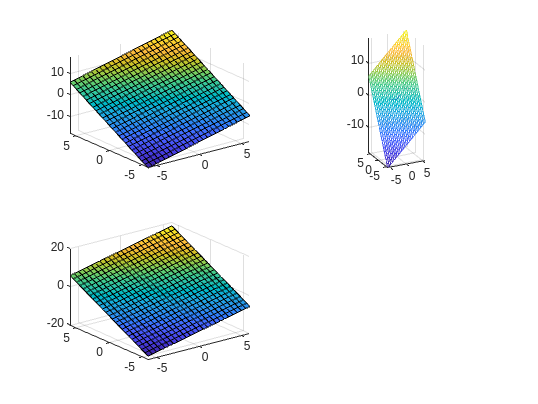


clf;

%Visualize what we did until now
[x,y]=meshgrid(linspace(-6,6,25)); A=[-2 1 0; 1 0 1]';  n1=null(A');

P1=(-n1(1)*x-n1(2)*y)/n1(3); %Cartesian equation of plane
subplot(2,2,1); surf(x,y,P1); axis('tight'); 
subplot(2,2,2); mesh(x,y,P1);
hidden off; hold on; axis equal; 
quiver3([0 0 ],[0 0 ],[0 0], A(1,:), A(2,:), A(3,:),1);
view([n1(1),n1(2),n1(3)]);

%Now let's see the orthonormal basis
A2=[double(u1) double(u2)];
n2=null(A2');
P2=(-n2(1)*x - n2(2)*y)/n2(3);
subplot(2,2,3); surf(x,y,P2);

Example: Compute an orthonormal basis, with respect to the standard dot produtct [-1,1], in the subspace S containing the real algebraic polynomials of degree at most 1.

dotProd=@(f,g) int(f*g,-1,1);
syms x real; A=[sym(1) x]

$$A = \left(\begin{array}{cc} 1 & x \end{array}\right)$$

v=sym('v',[1,2]);
u=sym('u',[1,2]);

v(1)=A(1);
u(1)=v(1)/sqrt(dotProd(v(1),v(1)))

$$u = \left(\begin{array}{cc} \frac{\sqrt{2}}{2} & u_{2} \end{array}\right)$$

v(2)=A(2)-dotProd(A(2),u(1))*u(1)

$$v = \left(\begin{array}{cc} 1 & x \end{array}\right)$$

u(2)=v(2)/sqrt(dotProd(v(2),v(2)));

disp(v)

$$\left(\begin{array}{cc} 1 & x \end{array}\right)$$

disp(u)

$$\left(\begin{array}{cc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} \end{array}\right)$$


disp(int(A'*A,-1,1))

$$\left(\begin{array}{cc} 2 & 0\\ 0 & \frac{2}{3} \end{array}\right)$$

disp(int(v'*v,-1,1))

$$\left(\begin{array}{cc} 2 & 0\\ 0 & \frac{2}{3} \end{array}\right)$$

disp(int(u'*u,-1,1))

$$\left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

dotProd=@(f,g) int(f*g,-1,1);
syms x real; A=[sym(1) x x^2]

$$A = \left(\begin{array}{ccc} 1 & x & x^{2} \end{array}\right)$$

v=sym('v',[1,3]);
u=sym('u',[1,3]);


v(1)=A(1);
u(1)=v(1)/sqrt(dotProd(v(1),v(1)))

$$u = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & u_{2} & u_{3} \end{array}\right)$$

v(2)=A(2)-dotProd(A(2),u(1))*u(1)

$$v = \left(\begin{array}{ccc} 1 & x & v_{3} \end{array}\right)$$

u(2)=v(2)/sqrt(dotProd(v(2),v(2)))

$$u = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & u_{3} \end{array}\right)$$

v(3)=A(3)-dotProd(A(3),u(1))*u(1) - dotProd(A(3),u(2))*u(2)

$$v = \left(\begin{array}{ccc} 1 & x & x^{2}-\frac{1}{3} \end{array}\right)$$

u(3)=v(3)/sqrt(dotProd(v(3),v(3)))

$$u = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & \frac{3\,\sqrt{2}\,\sqrt{5}\,\left(x^{2}-\frac{1}{3}\right)}{4} \end{array}\right)$$


disp(v)

$$\left(\begin{array}{ccc} 1 & x & x^{2}-\frac{1}{3} \end{array}\right)$$

u=simplify(u)

$$u = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{6}\,x}{2} & \frac{3\,\sqrt{2}\,\sqrt{5}\,\left(x^{2}-\frac{1}{3}\right)}{4} \end{array}\right)$$


disp(int(A'*A,-1,1)) %non-orthogonal

$$\left(\begin{array}{ccc} 2 & 0 & \frac{2}{3}\\ 0 & \frac{2}{3} & 0\\ \frac{2}{3} & 0 & \frac{2}{5} \end{array}\right)$$

disp(int(v'*v,-1,1)) %orthogonal

$$\left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & \frac{2}{3} & 0\\ 0 & 0 & \frac{8}{45} \end{array}\right)$$

disp(int(u'*u,-1,1)) %orthonormal

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$